# Control Script- Perfect

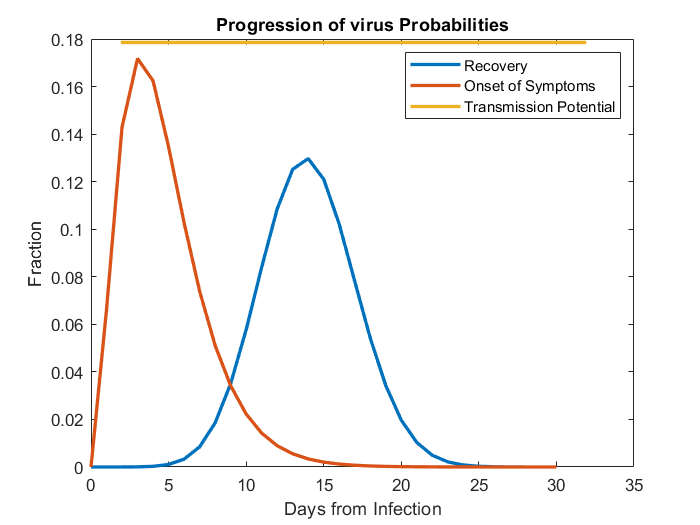

maskfactor = 0.3300

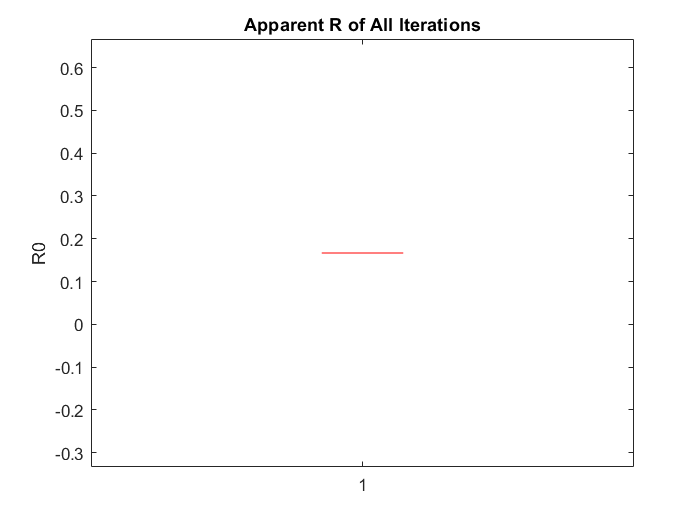

r0_all =     0.1667    2.4731    2.5113    2.4854    2.4930


maskfactor = 0.3300

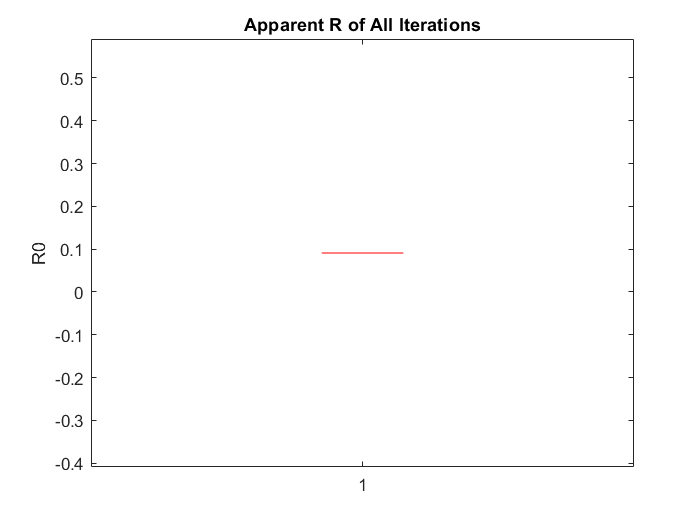

r0_all =     0.1667    0.0909    2.5113    2.4854    2.4930


maskfactor = 0.3300

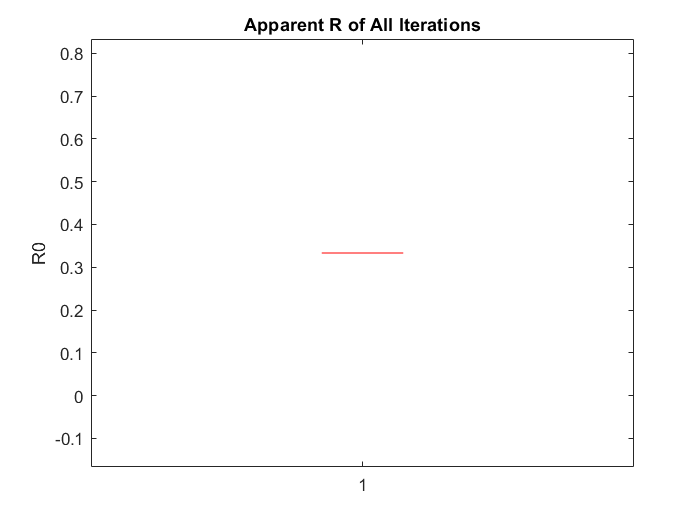

r0_all =     0.1667    0.0909    0.3333    2.4854    2.4930


maskfactor = 0.3300

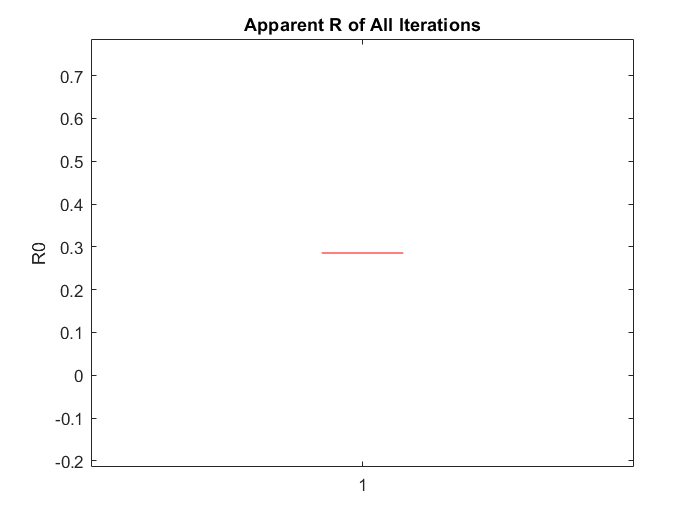

r0_all =     0.1667    0.0909    0.3333    0.2857    2.4930


maskfactor = 0.3300

r0_all =     0.1667    0.0909    0.3333    0.2857    0.2857


tests_conditions=[500,2500:2500:10000];
freq_conditions=[1:7,14];

% Number of times simulation runs
iterationsize = 1; 

for z=1:size(tests_conditions,2)
    numtest=tests_conditions(z);
    for y=1:size(freq_conditions,2)
        
        clear students
        testfreq=freq_conditions(y);
        
       addpath Scenarios_makeHeatmapRt\
       
        %Below, input your scenario of choice
        Scenario1_PerfectTestsUniformSpread
 
        r0_all(z,y)=median(r0sample)
        r0_sorted=sort(r0sample);
        r0_upper95(z,y)=r0_sorted(1);
    end
end

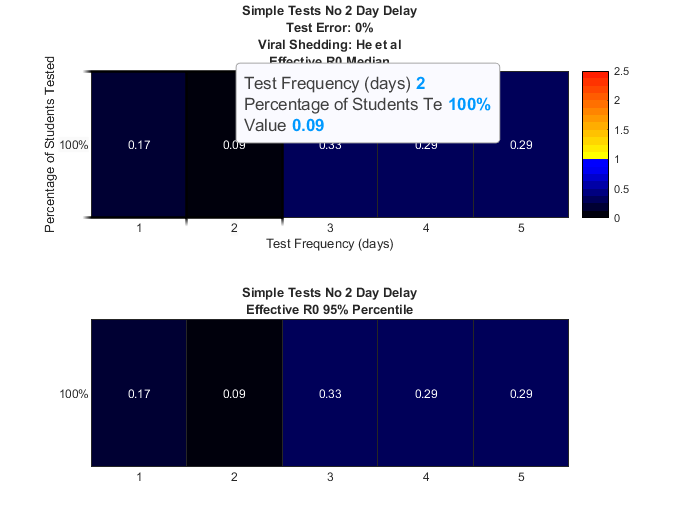

figure();
% heatmap subplots median and upper 95
map=[0, 0, 0.05; 0, 0, 0.2; 0, 0, 0.35; 0, 0, 0.5;0, 0, 0.65; 0, 0, 0.8;0, 0, 0.95;0, 0, 1.0;...
    1.0000,1,0;1.0000,0.92,0;1.0000,0.84,0;1.0000,0.76,0;1.0000,0.68,0;1.0000,0.60,0;1.0000,0.52,0;1.0000,0.44,0;...
    1.0000,0.36,0;1.0000,0.28,0;1.0000,0.20,0;1.0000,0.12,0];
subplot(2,1,1)
h=heatmap( r0_all,'colorlimits',[0,2.5],'Colormap',map,...
        'YData',string(tests_conditions/100)+'%', 'Xdata', string(freq_conditions),...
        'FontSize', 7);
    h.CellLabelFormat = '%.2f';
    title({'Simple Tests No 2 Day Delay','Test Error: 0%', 'Viral Shedding: He et al','Effective R0 Median'})
        xlabel('Test Frequency (days)')
        ylabel('Percentage of Students Tested')
 subplot(2,1,2)
 h=heatmap(r0_upper95,'colorlimits',[0,2.5],'Colormap',map,...
        'YData',string(tests_conditions/100)+'%', 'Xdata', string(freq_conditions),...
        'FontSize', 7,'ColorbarVisible','off');
    title({'Simple Tests No 2 Day Delay','Effective R0 95% Percentile'})
    h.CellLabelFormat = '%.2f';